syms s

sys = s / ( (s + 2*pi) * (s + 10000) )

$$sys = \frac{s}{\left(s+6.2832\right)\,\left(s+10000\right)}$$

sys = collect(sys, s)

$$sys = \frac{s}{s^{2}+1.0006e+04\,s+6.2832e+04}$$


sys_tf = sym2tf(sys)

sys_tf =
 
            s
  ---------------------
  s^2 + 10006 s + 62832
 
Continuous-time transfer function.



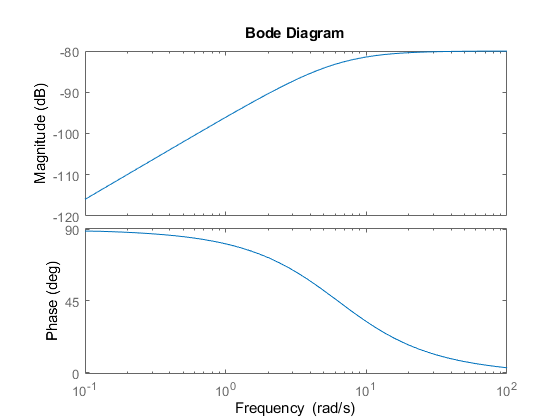


bode(sys_tf)

xlim([0.1 100])

clear ; close all ; clc

syms C_v C_m B R E P
% C_m = 0;

eq1 = E == R - (E*C_v1 + B*C_m1)*P_1

$$eq1 = \text{E}=R-P_{1}\,\left(B\,C_{\mathrm{m1}}+C_{\mathrm{v1}}\,\text{E}\right)$$

E = solve(eq1, E)

$$E = \frac{R-B\,C_{\mathrm{m1}}\,P_{1}}{C_{\mathrm{v1}}\,P_{1}+1}$$


eq2 = B == (E*C_v1 + B*C_m1) * P

$$eq2 = B=P_{1}\,\left(B\,C_{\mathrm{m1}}+\frac{C_{\mathrm{v1}}\,\left(R-B\,C_{\mathrm{m1}}\,P_{1}\right)}{C_{\mathrm{v1}}\,P_{1}+1}\right)$$


eq3 = solve(eq2, B)

$$eq3 = \frac{C_{\mathrm{v1}}\,P_{1}\,R}{C_{\mathrm{v1}}\,P_{1}-C_{\mathrm{m1}}\,P_{1}+1}$$


sys = eq3 / R

$$sys = \frac{C_{\mathrm{v1}}\,P_{1}}{C_{\mathrm{v1}}\,P_{1}-C_{\mathrm{m1}}\,P_{1}+1}$$

clear ; close all ; clc
disp('-------------------------------------')

-------------------------------------


syms C_v1 C_m1 C_v2 C_m2 P_1 P_2 B H R E G_1 G_2
% C_m = 0;
% C_m1 = 0;
% C_m2 = 0;
% P_2 = 0;

% eq1 = E == R - (E*C_v1 + B*C_m1)*P_1 - (E*C_v2 + B*C_m2)*P_2
eq1 = E == R - (E*C_v1 + B*C_m1)*P_1 - (E*C_v2 + B*C_m2)*P_2

$$eq1 = \text{E}=R-P_{1}\,\left(B\,C_{\mathrm{m1}}+C_{\mathrm{v1}}\,\text{E}\right)-P_{2}\,\left(B\,C_{\mathrm{m2}}+C_{\mathrm{v2}}\,\text{E}\right)$$


E = solve(eq1, E)

$$E = -\frac{B\,C_{\mathrm{m1}}\,P_{1}-R+B\,C_{\mathrm{m2}}\,P_{2}}{C_{\mathrm{v1}}\,P_{1}+C_{\mathrm{v2}}\,P_{2}+1}$$


eq2 = B == (E*C_v1 + B*C_m1)* P_1;
eq3 = H == (E*C_v2 + B*C_m2)* P_2;

eq4 = solve(eq2, B)

$$eq4 = -\frac{C_{\mathrm{v1}}\,P_{1}\,R}{\left(P_{1}\,\left(C_{\mathrm{m1}}-\frac{C_{\mathrm{v1}}\,\left(C_{\mathrm{m1}}\,P_{1}+C_{\mathrm{m2}}\,P_{2}\right)}{C_{\mathrm{v1}}\,P_{1}+C_{\mathrm{v2}}\,P_{2}+1}\right)-1\right)\,\left(C_{\mathrm{v1}}\,P_{1}+C_{\mathrm{v2}}\,P_{2}+1\right)}$$

eq5 = solve(eq3, H)

$$eq5 = P_{2}\,\left(B\,C_{\mathrm{m2}}-\frac{C_{\mathrm{v2}}\,\left(B\,C_{\mathrm{m1}}\,P_{1}-R+B\,C_{\mathrm{m2}}\,P_{2}\right)}{C_{\mathrm{v1}}\,P_{1}+C_{\mathrm{v2}}\,P_{2}+1}\right)$$


% sys = eq5 / R;

test = eq4;
test = simplify(expand(test))

$$test = \frac{C_{\mathrm{v1}}\,P_{1}\,R}{C_{\mathrm{v1}}\,P_{1}-C_{\mathrm{m1}}\,P_{1}+C_{\mathrm{v2}}\,P_{2}-C_{\mathrm{m1}}\,C_{\mathrm{v2}}\,P_{1}\,P_{2}+C_{\mathrm{m2}}\,C_{\mathrm{v1}}\,P_{1}\,P_{2}+1}$$


test = subs(eq5, B, eq4);
test = simplify(expand(test))

$$test = \frac{P_{2}\,R\,\left(C_{\mathrm{v2}}-C_{\mathrm{m1}}\,C_{\mathrm{v2}}\,P_{1}+C_{\mathrm{m2}}\,C_{\mathrm{v1}}\,P_{1}\right)}{C_{\mathrm{v1}}\,P_{1}-C_{\mathrm{m1}}\,P_{1}+C_{\mathrm{v2}}\,P_{2}-C_{\mathrm{m1}}\,C_{\mathrm{v2}}\,P_{1}\,P_{2}+C_{\mathrm{m2}}\,C_{\mathrm{v1}}\,P_{1}\,P_{2}+1}$$

% 
% eq5


clear ; clc

syms G_H_V G_H_M G_B B H E R

E = R - B - H

$$E = R-H-B$$

eq1 = H == G_H_V*E + G_H_M*B

$$eq1 = H=B\,G_{H,M}-G_{H,V}\,\left(B+H-R\right)$$

eq2 = solve(eq1, H)

$$eq2 = \frac{B\,G_{H,M}-B\,G_{H,V}+G_{H,V}\,R}{G_{H,V}+1}$$


eq3 = simplify(subs(eq2, G_H_M, 0))

$$eq3 = -\frac{G_{H,V}\,\left(B-R\right)}{G_{H,V}+1}$$



clear E
syms E
eq4 = E == R - E*G_B - H

$$eq4 = \text{E}=R-H-\text{E}\,G_{B}$$

E_temp = solve(eq4, E)

$$E\_temp = -\frac{H-R}{G_{B}+1}$$

eq5 = subs(H == G_H_V*E, E, E_temp)

$$eq5 = H=-\frac{G_{H,V}\,\left(H-R\right)}{G_{B}+1}$$


solve(eq5, H)

$$ans = \frac{G_{H,V}\,R}{G_{B}+G_{H,V}+1}$$